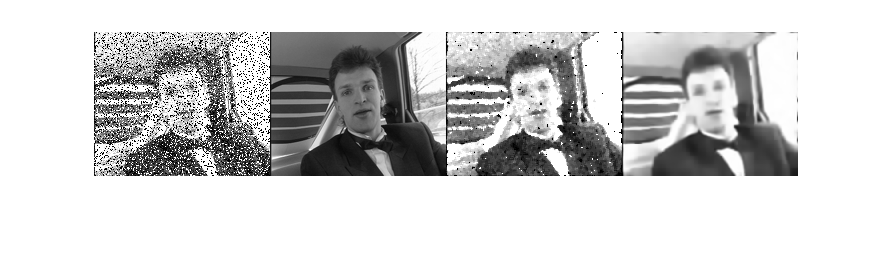

clc;
clear;
close all;

addpath("Adaptive_Median_Filter\");
addpath("BM3D-master\");

vid1 = yuv4mpeg2mov('Test_Videos/carphone.y4m');

%filtered_X = AdapMedFilter(X, 9);
%imshow([vid1(1).cdata X filtered_X])

[n1,n2,~]=size(vid1(1).cdata);
no_of_frames= 15; 
frame_num=1;
tau = 0.0001;
iters=20;
frames_coloured=uint8(zeros([n1 n2 3 15]));
frames= uint8(zeros([n1 n2 15]));
noisy_frames= uint8(zeros([n1 n2 no_of_frames]));
filtered_frames= uint8(zeros([n1 n2 no_of_frames]));
noisy_frames_coloured=uint8(zeros([n1 n2 3 no_of_frames]));
for i=1:no_of_frames
    frames(:,:,i)= rgb2gray(vid1(i).cdata);
    frames_coloured(:,:,:,i)= vid1(i).cdata;
    noisy_frames(:,:,i) = noise(frames(:,:,i), 20, 2, 0.3);
    noisy_frames_coloured(:,:,:,i) = noise(frames_coloured(:,:,:,i), 20, 2, 0.3);
    filtered_frames(:,:,i) = medfilt2(noisy_frames(:,:,i));
end
[~, Y]= VBM3D(filtered_frames,100, 0, 0);
Y=Y*255;

figure; imshow([noisy_frames(:,:,1) frames(:,:,1) filtered_frames(:,:,1) Y(:,:,1)])

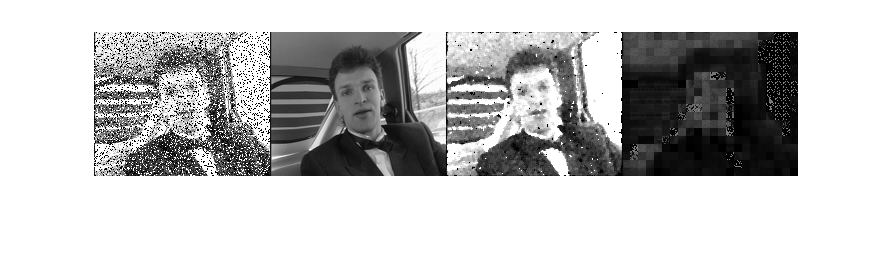


%frames_coloured-frames_coloured(:,1,1,1)\\

missing_pixels = (filtered_frames == noisy_frames);
patches = uint8(zeros([8*8 n1/8 n2/8 no_of_frames]));
missing = false([8*8 n1/8 n2/8 no_of_frames]);

for i=1:no_of_frames
   for j = 1:n1/8
       for k = 1:n2/8
           patches(:,j,k,i) = reshape(filtered_frames(8*(j-1)+1:8*(j-1)+8 , 8*(k-1)+1:8*(k-1)+8, i), [64 1]);
           missing(:,j,k,i) = reshape(missing_pixels(8*(j-1)+1:8*(j-1)+8 , 8*(k-1)+1:8*(k-1)+8, i), [64 1]);    
       end
   end
end

denoised_patches = uint8(zeros([8*8 n1/8 n2/8 no_of_frames]));
for j=1:n1/8
    for k=1:n2/8
        [patch_matrix, Omega, find]=patchmatcher(patches,j,k,frame_num,missing);
        denoised_patch = fixed_point_iteration(patch_matrix,Omega,tau,iters,find,no_of_frames);
        denoised_patches(:,j,k,frame_num) = denoised_patch;
    end
end
recon=uint8(zeros([n1,n2]));

for j=1:n1/8
    for k=1:n2/8
        recon(8*(j-1)+1:8*j,8*(k-1)+1:8*k) = uint8(reshape(denoised_patches(:,j,k,frame_num),[8 8]));
    end
end

figure; imshow([noisy_frames(:,:,1) frames(:,:,1) filtered_frames(:,:,1) recon]);